# Extracting Data from SeaDAS into MATLAB

Description: This live script walks thorugh using functions to extract Level 2 products and to 

% Set Up
clear
clc
close all 

% Change to virginiaCoast Folder
cd /Users/kellyluis/Desktop/Projects/virginiaCoast/

% Add Functions to Path
addpath('/Users/kellyluis/Desktop/Projects/virginiaCoast/functions')

## readL2 

This function takes the filename of a Level 2 SeaDAS product and writes the atmospherically corrected information into a structure.

cd('datasets/')
filename = 'L2017355154052.L2_LAC_OC';

% Read File into MA
L8 = readL2(filename);

## extractC

This function gathers raster information around a coordinate of interest by extracting a 3x3 box centered on the coordinate of interest.

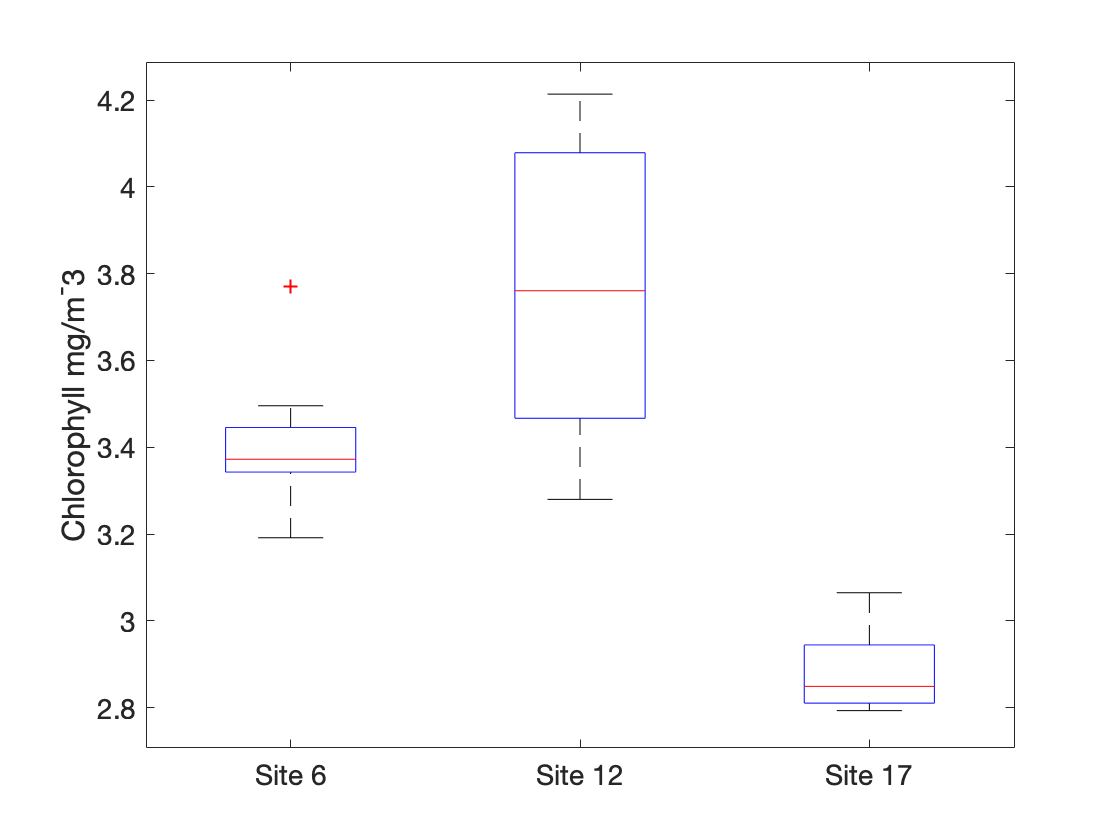

parameter = L8.chl;
coord = [37.36764 -75.73592; 37.4670924 -75.668335; 37.29038 -75.784927];
slat = L8.Lat;
slon = L8.Lon;
site_names = {'Site 6','Site 12', 'Site 17'};

% Extract Coordinates of Interest
chlBox = extractC(parameter, slat, slon, coord);

% Quick Visualization
figure(1)
boxplot(chlBox,'Labels',site_names)
ylabel('Chlorophyll mg/m^-3')
set(gca,'FontSize', 14)

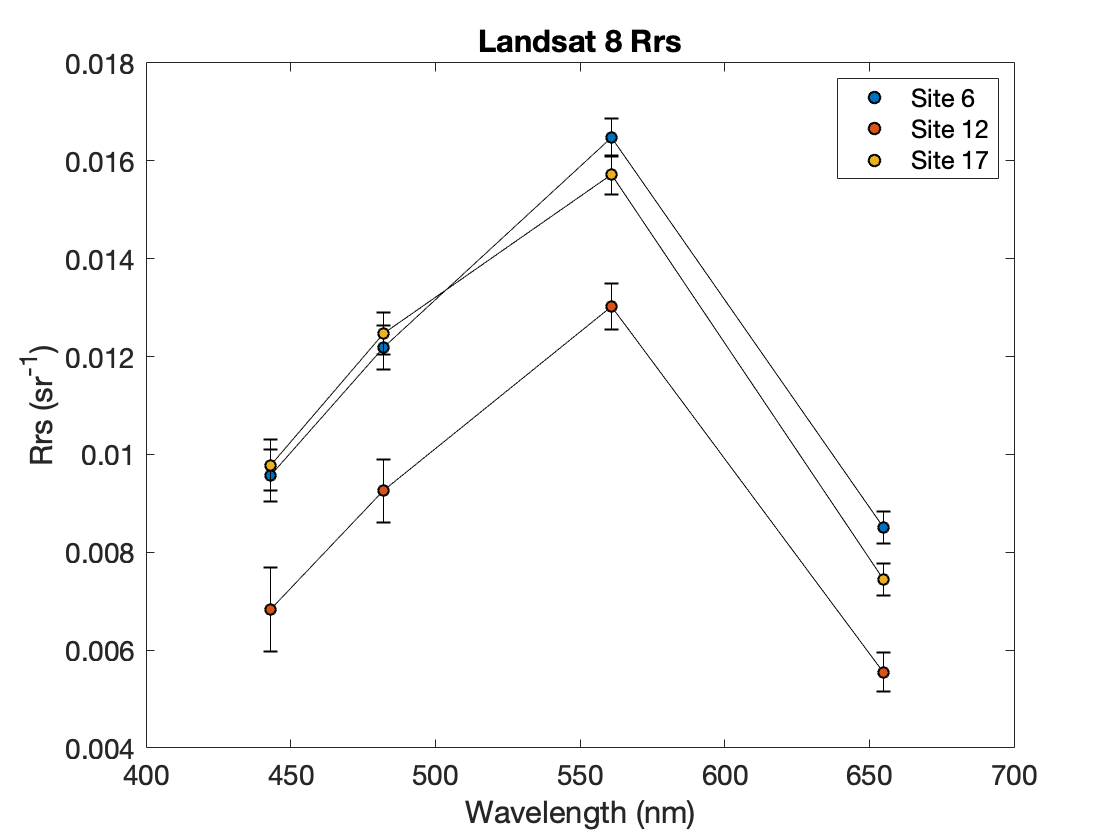

% Loop Through Multiple Geophysical Parameters 
geop = {'rrs_443';'rrs_482';'rrs_561';'rrs_655'};

for param = 1:length(geop)
    L8.coord.(geop{param}) = extractC(L8.(geop{param}), L8.Lat, L8.Lon, coord);
end

% Gather Stats on Rrs 
for param = 1:length(geop)
    for site = 1:size(coord,1)
        rrs_mean(param,site) = nanmean(L8.coord.(geop{param})(:,site));
        rrs_std(param,site) = nanstd(L8.coord.(geop{param})(:,site));
    end
end

% Plot Rrs stats by Wavelength
wlc = regexp(geop,'\d+(\.)?(\d+)?','match');
wl = str2double([wlc{:}]);

figure(2)

for site = 1:size(coord,1)
    errorbar(wl,rrs_mean(:,site),rrs_std(:,site),'k','HandleVisibility','off')
    hold on
    scatter(wl,rrs_mean(:,site),30,'filled','MarkerEdgeColor','k','DisplayName',site_names{site})
end

legend
xlabel('Wavelength (nm)')
ylabel('Rrs (sr^{-1})')
title('Landsat 8 Rrs')
set(gca,'Fontsize',14)

## Loop Through Multiple Images

% Put all Level 2 files in a MATLAB directory
sdir = dir('/Users/kellyluis/Desktop/Projects/virginiaCoast/datasets/*OC');

% Specify Variables of Interest
vi = {'Lat','Lon','kd_490','chl','rrs_443','rrs_482','rrs_561','rrs_655','l2_flags'};

for file = 1:length(sdir)
    
    % Read Files
    filename = sdir(file).name;
    L8_raw = readL2(filename);
    
    % Gather Datetime Information
    L8coord.date(file) = L8_raw.date;
    
    % Gather Variables of Interest at Coordinates of Interest
    for param = 1:length(vi)
        L8coord.(vi{param})(:,:,file) = extractC(L8_raw.(vi{param}), L8_raw.Lat, L8_raw.Lon, coord);
    end
    
end